% Expand in the Fourier series a periodic function given 
% on the half-period [0;2] by the equation f(x)=x-1/2*x^2.

clear
syms x real;
syms pi;
% 2) odd function
f=x-1/2*x^2

$$f = x-\frac{x^{2}}{2}$$

% f=x-1/2*x^2
L=2

L = 2

digits(4)

a0=sym(0)

$$a0 = 0$$

% 0
syms m integer;
assume(m>=1)
a(m)=sym(0)

$$a(m) = 0$$

% 0
af(m)=a(m)*cos(m*pi*x/L)

$$af(m) = 0$$

% 0

b(m)=(2/L)*int(f*sin(m*pi*x/L),x,0,2)

$$b(m) = \frac{16\,{\sin\left(\frac{\pi \,m}{2}\right)}^{2}}{m^{3}\,\pi^{3}}-\frac{4\,\sin\left(\pi \,m\right)}{m^{2}\,\pi^{2}}$$

% (16*sin((pi*m)/2)^2)/(m^3*pi^3) - (4*sin(pi*m))/(m^2*pi^2)
b(m)=simplify(b(m))

$$b(m) = \frac{4\,\left(4\,{\sin\left(\frac{\pi \,m}{2}\right)}^{2}-\pi \,m\,\sin\left(\pi \,m\right)\right)}{m^{3}\,\pi^{3}}$$

% (4*(4*sin((pi*m)/2)^2 - m*pi*sin(pi*m)))/(m^3*pi^3)
%     =2*(1-(-1)^m)            =0 
b(m)=simplify(subs(b(m),[sin(pi*m) sin((pi*m)/2)^2],[0 (1-(-1)^m)/2]))

$$b(m) = -\frac{8\,{\left(-1\right)}^{m}-8}{m^{3}\,\pi^{3}}$$

% -(8*(-1)^m - 8)/(m^3*pi^3)
bf(m)=b(m)*sin(m*pi*x/L)

$$bf(m) = -\frac{\sin\left(\frac{\pi \,m\,x}{2}\right)\,\left(8\,{\left(-1\right)}^{m}-8\right)}{m^{3}\,\pi^{3}}$$

% -(sin((pi*m*x)/2)*(8*(-1)^m - 8))/(m^3*pi^3)
abf(m)=af(m)+bf(m)

$$abf(m) = -\frac{\sin\left(\frac{\pi \,m\,x}{2}\right)\,\left(8\,{\left(-1\right)}^{m}-8\right)}{m^{3}\,\pi^{3}}$$

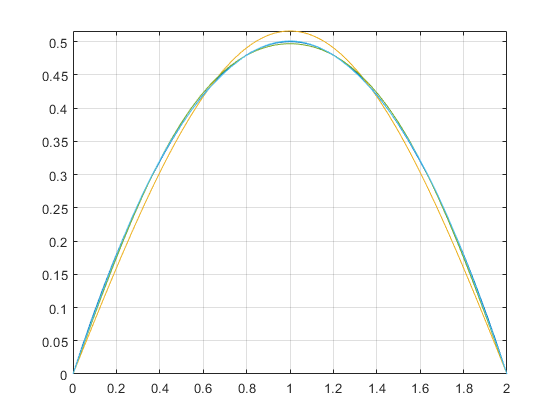

% -(sin((pi*m*x)/2)*(8*(-1)^m - 8))/(m^3*pi^3)
fplot(f,[0 2])
hold on

f1=a0/2;
for m=1:5
    m1(m)=m;
    a1(m)=a(m);
    b1(m)=b(m);
    abf1(m)=abf(m);
    f1=f1+abf(m);
    fplot(f1,[0 2]);
    grid on
end
hold off


disp(f1);

$$\frac{16\,\sin\left(\frac{\pi \,x}{2}\right)}{\pi^{3}}+\frac{16\,\sin\left(\frac{3\,\pi \,x}{2}\right)}{27\,\pi^{3}}+\frac{16\,\sin\left(\frac{5\,\pi \,x}{2}\right)}{125\,\pi^{3}}$$

% (16*sin((pi*x)/2))/pi^3 + (16*sin((3*pi*x)/2))/(27*pi^3) + (16*sin((5*pi*x)/2))/(125*pi^3)

a0/2

$$ans = 0$$

% 0
ft=[m1;a1;b1;abf1];
ft'

$$ans = \left(\begin{array}{cccc} 1 & 0 & \frac{16}{\pi^{3}} & \frac{16\,\sin\left(\frac{\pi \,x}{2}\right)}{\pi^{3}}\\ 2 & 0 & 0 & 0\\ 3 & 0 & \frac{16}{27\,\pi^{3}} & \frac{16\,\sin\left(\frac{3\,\pi \,x}{2}\right)}{27\,\pi^{3}}\\ 4 & 0 & 0 & 0\\ 5 & 0 & \frac{16}{125\,\pi^{3}} & \frac{16\,\sin\left(\frac{5\,\pi \,x}{2}\right)}{125\,\pi^{3}} \end{array}\right)$$

% [ 1, 0,       16/pi^3,         (16*sin((pi*x)/2))/pi^3]
% [ 2, 0,             0,                               0]
% [ 3, 0,  16/(27*pi^3),  (16*sin((3*pi*x)/2))/(27*pi^3)]
% [ 4, 0,             0,                               0]
% [ 5, 0, 16/(125*pi^3), (16*sin((5*pi*x)/2))/(125*pi^3)]

syms m k;
abf2(k)=subs(abf(m),m,2*k-1)

$$abf2(k) = -\frac{\sin\left(\frac{\pi \,x\,\left(2\,k-1\right)}{2}\right)\,\left(8\,{\left(-1\right)}^{2\,k-1}-8\right)}{\pi^{3}\,{\left(2\,k-1\right)}^{3}}$$

% -(sin((x*pi*(2*k - 1))/2)*(8*(-1)^(2*k - 1) - 8))/(pi^3*(2*k - 1)^3)
%                            =-8
abf2(k)=16*sin((x*pi*(2*k - 1))/2)/(pi^3*(2*k - 1)^3)

$$abf2(k) = \frac{16\,\sin\left(\frac{\pi \,x\,\left(2\,k-1\right)}{2}\right)}{\pi^{3}\,{\left(2\,k-1\right)}^{3}}$$


for k=1:3
    k3(k)=k;
    abf3(k)=abf2(k);
end
ft2=[k3;abf3]

$$ft2 = \left(\begin{array}{ccc} 1 & 2 & 3\\ \frac{16\,\sin\left(\frac{\pi \,x}{2}\right)}{\pi^{3}} & \frac{16\,\sin\left(\frac{3\,\pi \,x}{2}\right)}{27\,\pi^{3}} & \frac{16\,\sin\left(\frac{5\,\pi \,x}{2}\right)}{125\,\pi^{3}} \end{array}\right)$$

ft2'

$$ans = \left(\begin{array}{cc} 1 & \frac{16\,\sin\left(\frac{\pi \,x}{2}\right)}{\pi^{3}}\\ 2 & \frac{16\,\sin\left(\frac{3\,\pi \,x}{2}\right)}{27\,\pi^{3}}\\ 3 & \frac{16\,\sin\left(\frac{5\,\pi \,x}{2}\right)}{125\,\pi^{3}} \end{array}\right)$$

% [ 1,         (16*sin((pi*x)/2))/pi^3]
% [ 2,  (16*sin((3*pi*x)/2))/(27*pi^3)]
% [ 3, (16*sin((5*pi*x)/2))/(125*pi^3)]